Check Map generated

% Load rosbag data 
bagSelect = rosbag('test2.bag');

% Capture messages on topic 
encoderLog = select(bagSelect, 'Topic','/zlac8015d/encoder');
mapLog = select(bagSelect, 'Topic', '/slamware_ros_sdk_server_node/map');

% Capture data in messages
mapData = readMessages(mapLog);
map = readOccupancyGrid(mapData{1})

map =   occupancyMap with properties:

             XWorldLimits: [-4.1500 18.0000]
             YWorldLimits: [-1.8000 2.5500]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [-4.1500 -1.8000]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 20
                 GridSize: [87 443]
             XLocalLimits: [0 22.1500]
             YLocalLimits: [0 4.3500]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [-4.1500 -1.8000]


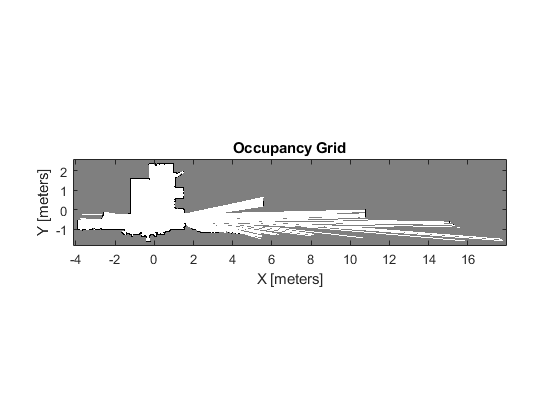


% Display a map 
show(map)